**Numerical Methods Final Exam 2022 - Solutions**

1. Three compression tests were carried out on a spring. In each test the displacement was measured at the same values of applied force.

The results were:

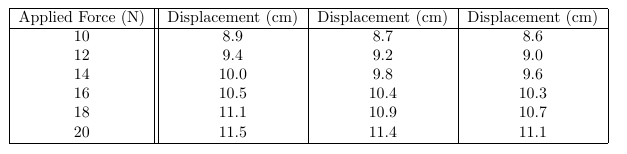

Plot the data then use linear regression to estimate the spring constant in kN/m. Plot the regression line on the same figure as the data.

disp('----------------------------------------------------- Q1 ---------------------------------------------------------')

----------------------------------------------------- Q1 ---------------------------------------------------------


N = repelem([10, 12, 14, 16, 18, 20], 3)';
KN = N/1000

KN =    0.010000000000000
   0.010000000000000
   0.010000000000000
   0.012000000000000
   0.012000000000000
   0.012000000000000
   0.014000000000000
   0.014000000000000
   0.014000000000000
   0.016000000000000


D = [8.9, 8.7, 8.6, 9.4, 9.2, 9, 10, 9.8, 9.6, 10.5, 10.4, 10.3, 11.1, 10.9, 10.7, 11.5, 11.4, 11.1]/100;

a = polyfit(KN, D, 1);
newY = polyval(a, KN)

newY =    0.087253968253968
   0.087253968253968
   0.087253968253968
   0.092596825396825
   0.092596825396825
   0.092596825396825
   0.097939682539683
   0.097939682539683
   0.097939682539683
   0.103282539682540


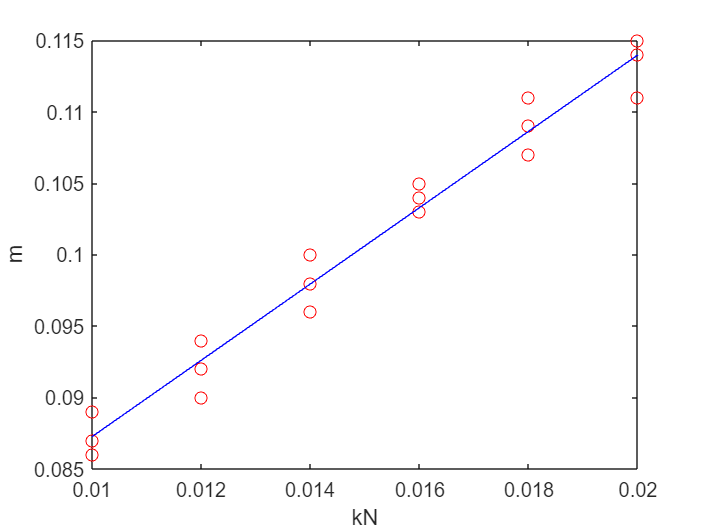


plot(KN, D, 'ro')
hold on
plot(KN, newY, 'b')
xlabel('kN')
ylabel('m')


disp('Spring Constant : ')

Spring Constant : 


disp(a(2))

   0.060539682539683



2. The following data is to be fit to an equation of the form,

$$z = Ae^{Bx}y^C$$,

where A, B and C are constants. 

Use linearisation and regression to estimate the values of A, B, and C then use the fitted equation to estimate the value of z at the point $$(x,y) = (2.7, 3.3)$$.

Data:

% Enter solution here
disp('----------------------------------------------------- Q2 ---------------------------------------------------------')

----------------------------------------------------- Q2 ---------------------------------------------------------


% exponential form slide 7
% exponential model = alpha*e^(beta*x)
% log(ab) = log(a) + log(b)
% log(e) = 1
% log(A^2) = 2 log (A)
% exp(log(A)) = A

% Data
x = [1 2.2 3.5 4.5 5.6 7.8];
y = [0.3 1.7 3.4 5.8 8.8 11];
z = [0.31 0.71 0.37 0.22 0.10 0.01];

% Enter solution here
% take log both side
% find log(z), x, log(y)
% log(z) = log(A) + Bx + clog(y)
logZ = log(z);
logY = log(y);
coeff = multipleLinearRegression(x', logY', logZ')

coeff =    1.583794693094909
  -1.191997843395857
   1.292058302045779



% x = 1.5838
% log(y) = -1.1920
% log(Z) = 1.2921
A = coeff(1)

A =    1.583794693094909


B = exp(coeff(2))

B =    0.303614084350359


C = exp(coeff(3))

C =    3.640271628379933



z = A * exp(B * 2.7) * 3.3 ^ C

z =      2.774896924738164e+02


3. Use a cubic **Lagrange** interpolant on the data below to estimate the following:

    a. The value of $f(x)$ when $x = 4.95$.

    b. The value of $x$ when $f(x) = 1.88$.

% Enter solution here


4. Approximate the following multiple integrals using any method (Matlab built-ins are recommended for highest accuracy):

    a. $\int\limits_{0}^{2}\int\limits_{y^3}^{4\sqrt{2y}} (x^2y - xy^2) \, dx \, dy$

    b. $\int\limits_{0}^{2}\int\limits_{0}^{4-x^2}\int\limits_{0}^{x} \sin(2z)e^{-x} \, dy \, dz \, dx$

% Enter solution here
disp('------------------------------------ Q1 --------------------------------------------')

------------------------------------ Q1 --------------------------------------------


f = @(y, x) (x.^2).*y - x.*(y.^2);
area = integral2(f, 0, 2, @(y)y.^3, @(y)4.*sqrt(2.*y));
disp('a.')

a.


disp(area)

  97.431457412759798




f = @(x, y, z) sin(2.*z).*exp(-z);
format long
area = integral3(f, 0, 2, 0, @(x)x, 0, @(x, y)4-x.^2);
disp('b.')

b.


disp(area)

   0.718699562021940



5. Answer the following questions for the integral:


$$\int\limits_{0}^{3\pi} (8 + \cos(x^2 - 3x)) \, dx$$


    a. Estimate the integral's value using 4 point Gauss-Legendre quadrature.

    b. What is the minimum number of partitions (value of $n$) needed to use Simpson's 1/3 rule to estimate the integral if we want the absolute approximate error to be less then 0.01? Demonstrate that your answer is correct.

% Enter solution here

6. The data below represents an objects position (m) measured at different times (s). Use a centred finite difference approach to estimate the time when the object experienced zero jerk.

**Reminder:** Jerk is the derivative of acceleration.

% Enter solution here
h = 2                   %step size of x

h =      2


t = 0:2:16

t =      0     2     4     6     8    10    12    14    16


st = [7.2, 0.7040, 0.3040, 2.0640, 3.5840, 4.0000, 3.9840, 5.7440, 13.0240]

st =    7.200000000000000   0.704000000000000   0.304000000000000   2.064000000000000   3.584000000000000   4.000000000000000   3.984000000000000   5.744000000000000  13.023999999999999


coeff = polyfit(t, st, 1) % measure speed coeff v = s/t

coeff =    0.397600000000000   1.331199999999999



% jerk is taking 3rd derivative since distance --> Velocity -->
% Acceleration --> Jerk
% 0 jerk = constant acceleration = linear velocity = quadratic distance
% formula for improved 3rd derivative is
% -f(xi+3) + 12f(xi+2)-39f(xi+1)+56f(xi)-39f(xi-1)+12f(xi-2)-f(xi-3)/6h^4
% Step 2: Use Centred Finite Difference to estimate. Note = s' => v. v' => a. a' => J
j_cd = ( -3.984 + 12*4 - 39*3.584 + 56*2.064 - 39*0.304 + 12*0.704 - 7.2 )./(6*h.^4);

--- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.

% Enter solution here

function [coefficients] = multipleLinearRegression(x, y, z)
% remember to flip x, y, and z
    a = [ones(size(x)) x y]; % create matrix of 1s size x
    b = (a'*a)\(a'*z); % find coefficient
    coefficients = b;
end

function IntegralVal = simpsons_1_3_rule(f, a, b, n)
    % Check for even value of n (Simpson's 1/3 rule requires even number of subintervals)
    if mod(n, 2) ~= 0
        error('Number of subintervals (n) must be even for Simpson''s 1/3 rule.');
    end
    h = (b - a) / n;
    x = a:h:b;
    
    IntegralVal = (h / 3) * (f(a) + 4 * sum(f(x(2:2:end-1))) + 2 * sum(f(x(3:2:end-2))) + f(b));
end